## Theoretical part

Let $\mu >0$ and $\sigma^2 >0$ and let $Z\sim \textrm{WN}\left(\mu ,\sigma^2 \right)$. Let then Y be the process defined by $Y_t =\sum_{j=0}^q \theta_j Z_{t-j}$ for some coefficients $\theta_1 ,\ldotp \ldotp \ldotp ,\theta_q \in \ \underline{R} ,q\ \in \ \underline{N} ,$ with $\theta_0 =1$. As we will see in the lectures,  is called a moving average process of order .

### **a.) **

Show that for any $\left(t,h\right)\ \in \ {\underline{Z} }^2 ,\ E\left(Y_t \right)=E\left(Y_{t+h} \right)$;


$$r=t,\ s=t+h$$



$$E\left(Z_r \right)=E\left(Z_s \right)=\mu$$



$$E\left(Y_r \right)=E\left(\sum_{j=0}^q \theta_j Z_{r-j} \right)\ =\mu \ E\left(\sum_{j=0}^q \theta_j \right)=\mu \sum_{j=0}^q \theta_j =E\left(Y_s \right)$$


### **b.) **

Show that $\left(t,s,h\right)\ \in \ Z^3 \ ,\ Cov\left(Y_t ,Y_{t+h} \right)=Cov\left(Y_s ,Y_{s+h} \right)$*;*


$$\gamma_Y \left(h\right):=Cov\left(Y_t ,Y_{t+h} \right)$$



$$\textrm{Co}v\left(Y_t ,Y_{t+h} \right)=E\left\lbrack \left(Y_t -\mu_Y \left(t\right)\right)\left(Y_{t+h} -\mu_Y \left(t+h\right)\right)\right\rbrack =E\left(Y_t Y_{t+h} \right)-\mu_Y \left(t\right)\mu_Y \left(t+h\right)=E\left(Y_t Y_{t+h} \right)-\mu_Y \left(t{\left.\right)}^2 \right.$$



$$\textrm{Co}v\left(Y_s ,Y_{s+h} \right)=E\left\lbrack \left(Y_s -\mu_Y \left(s\right)\right)\left(Y_{s+h} -\mu_Y \left(s+h\right)\right)\right\rbrack =E\left(Y_s Y_{s+h} \right)-\mu_Y \left(s\right)$$


Since; $E\left(Y_t \right)=E\left(Y_{t+h} \right)=\mu_Y \left(t\right)=\mu_Y \left(t+h\right)$,


$$\textrm{Co}v\left(Y_t ,Y_{t+h} \right)=E\left(Y_t Y_{t+h} \right)-{\mu_Y }^2$$



$$\textrm{Co}v\left(Y_s ,Y_{s+h} \right)=E\left(Y_s Y_{s+h} \right)-{\mu_Y }^2$$



$$E\left(Y_t Y_{t+h} \right)=E\left(\sum_{j=0}^q \theta_j Z_{t-j} \ *\ \sum_{j=0}^q \theta_j Z_{t+h-j} \right)=E\left(Y_t \right)E\left(Y_{t+h} \right)=E{\left(Y_t \right)}^2 =E{\left(Y_s \right)}^2$$


$Z_t$ are uncorrelated (zero $\textrm{Co}v:\;E\left\lbrack Z_a Z_b \right\rbrack \ -\ E\left\lbrack Z_a \ \right\rbrack E\left\lbrack Z_b \right\rbrack =0\$), but not necessarily independent or iid

### **c.) **

Show that $Y$ is stationary and give its autocovariance function.

Weak:$\mu_Y \left(t\right)=\textrm{constant}$ and $\gamma_Y \left(r,s\right)=\gamma_Y \left(r+h,s+h\right)$

Strict: above + $Y$ is IID (i.e. $Z$ is iid)

ACF:$\gamma_Y \left(h\right):=Cov\left(Y_{t+h} ,Y_t \right)=\gamma_Y \left(h,0\right)=\gamma_Y \left(t+h,t\right)$

### **d.) **

Prove that if $Z$ is a Gaussian process, then $Y_t$ is independent of $Y_{t+h}$ for any $t\ \in \ Z$ and ${\left|h\right|}>q$.

If $Z$ is Gaussian then it is necessarily iid and so is $Y$ assuming ${\left|h\right|}\ge q$. When ${\left|h\right|}<q$, we have overlap (re-used) $Z^{\prime }$s in $\left\lbrace \ Y_t =\sum_{j=0}^q \theta_j Z_{t-j} ,Y_{t+h} =\sum_{j=0}^q \theta_j Z_{t+h-j} \right\rbrace$and the number of re-used $Z^{\prime }$s is $q-{\left|h\right|}$.

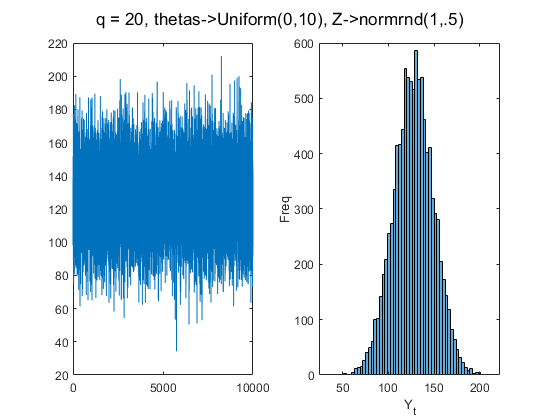

clear all
T = 10000;
q = 20;
Y = zeros(1,T);
theta = 10 * rand(1,q+1);
mu = 1;
sigma2 = .5;
for t = 1:T
    sm = 0;
    for j = 1:q+1
        sm = sm + theta(j)*normrnd(mu,sqrt(sigma2));
    end
    Y(t) = sm;
end
subplot(1,2,1)
xlabel('t')
ylabel('Y_t')
plot(Y)
subplot(1,2,2)
histogram(Y)
xlabel('Y_t')
ylabel('Freq')
sgtitle(['q = ' num2str(q) ', thetas->Uniform(0,10), Z->normrnd(1,.5)'])

## Practical part

### **1.)**

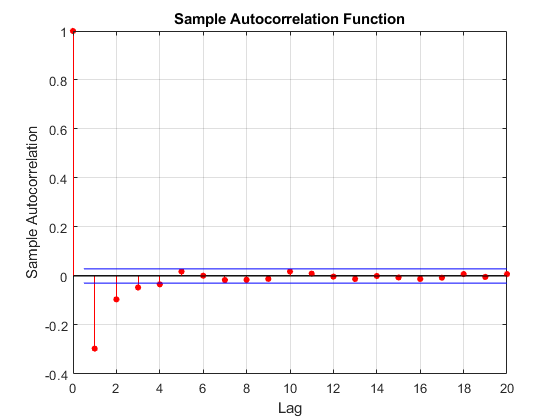

clf
d = readtable('intel.csv');
X_miss = d.VolumeMissing;
Y_miss = log(X_miss(2:end)) - log(X_miss(1:end-1));
tList = 1:length(Y_miss);
autocorr(Y_miss, 20)

We look at the ACF to determine q via the bounds +/- 1.96/srqt(n) (95% confidence interval) gain from the autocorr function plot above. Choosing q to be the last value of h that is outside the confidence interval. Assuming that all h after is IID noise, as they are all within the confidence interval (h=5...20). From this we assume that a reasonable value of q is 4.

### 2.)

q = 4;
acf = autocorr(Y_miss, 20);
acf = acf(1:q+1);
M = find(isnan(Y_miss));

We now want to solve the **a** for;


$$\left\lbrack \begin{array}{cccc}
1 & \phi_1  & \cdots  & \phi_1^{n-1} \\
\phi_1  & 1 & \cdots  & \phi_1^{n-2} \\
\vdots  & \vdots  & \ddots  & \vdots \\
\phi_1^{n-1}  & \phi_1^{n-2}  & \cdots  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\phi_1 \\
\phi_1^2 \\
\vdots \\
\phi_1^n 
\end{array}\right\rbrack$$


We set q to be n, as values above is IDD noise and create the first matrix;

acfMatrix = zeros(q,q);
reverseAcf = flip(acf(2:q));
combinedAcf = [reverseAcf' acf(1:q)']';

for row = 1:1:q
    tmpAcf = combinedAcf(q-row+1:2*q-row);
    for col = 1:1:q
        acfMatrix(row,col)=tmpAcf(col);
    end
end

Solve the system to get $a_1 \cdots a_n$

a = linsolve(acfMatrix,acf(2:q+1));